# Rad229_EPI_T2star_Blurring_Demo demonstrates T2* blurring in echo planar imaging (EPI).

% These questions can be used to further explore the code and concepts.

%     1) The apparent spatial resolution of tissues with a long T2* is different when compared to short T2* tissues. How is it different? Why? 

%     2) What limits echo spacing from being very, very short? If the dwell time for the readout is as short as possible, then what is the approximate ratio of phase encode to frequency encode bandwidth?

%     3) [Advanced] Code an example of spin-echo EPI and compare the contrast and resolution differences.

%     4) [Advanced] Code an example of T2*-blurring and chemical shift artifacts in EPI. 

DBE@STANFORD.EDU (May 2020) for Rad229

## Default parameters

acq.Nx = 128;   % Matrix size (N x N)
acq.ESP = 10e-3; % EPI echo spacing [s]

obj.T2star = [10e-3 25e-3 50e-3 100e-3 1000e-3]; % Range of T2-star values [s]

## Plot the T2-star decay curves

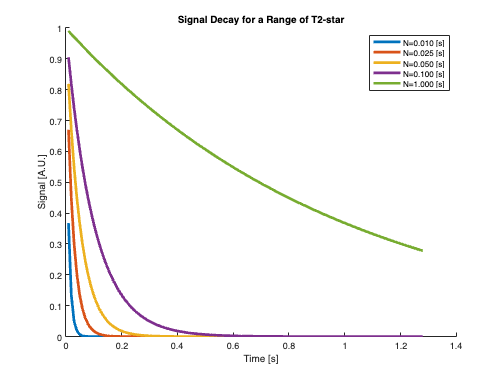

t = acq.ESP * ( 1  : acq.Nx ); 
for n = 1 : numel(obj.T2star)
  S(: , n ) = exp( - t / obj.T2star( n ) );
end

figure; hold on;
  p = plot( t , S ); set( p , 'LineWidth' , 3);
  legend(cellstr(num2str(obj.T2star', 'N=%2.3f [s]')));
  title('Signal Decay for a Range of T2-star')
  ylabel('Signal [A.U.]'); xlabel(['Time [s]']);

## Create a resolution phantom (decay with T2-star, add noise)

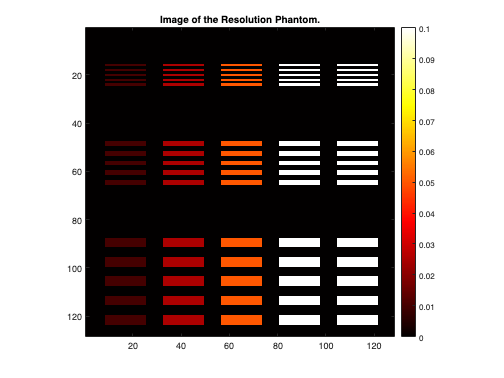

P = Rad229_MRI_Resolution_Phantom( acq , obj );
  figure; imagesc( P ); colormap(hot); colorbar; axis equal tight; caxis([0 0.1]);
  title('Image of the Resolution Phantom.');


% Create a time series of phantoms with T2-star decay and noise
Obj = repmat(P,[1 1 acq.Nx]);
for n = 1 : acq.Nx
  Obj( : , : , n ) = exp( -( n * acq.ESP ) ./ P );
end

% Create a noisy object 
Obj = Obj + ( randn(size(Obj)) + 1i * randn(size(Obj)) ) / 20; % Add some complex noise

disp('Images of the object as it decays. Some objects disappear!')

Images of the object as it decays. Some objects disappear!


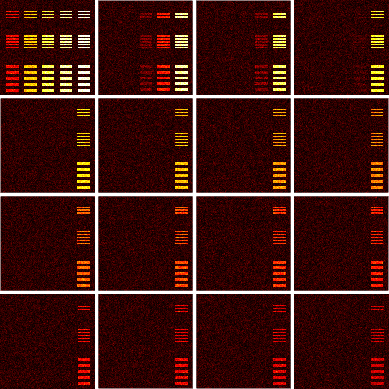

figure; imagescn( abs( Obj( : , : , 1 : 8 : end ) ) , [0 1] ); colormap(hot);


% Define the object's k-space
kspc = zeros(size(Obj));
for n=1:acq.Nx
  kspc(:,:,n)=fftshift(fft2(Obj(:,:,n))); % Define the k-space
end

## Simulate the TOP-DOWN EPI trajectory

k_epi = zeros(acq.Nx);
for n = 1 : acq.Nx
  k_epi( n , : ) = kspc( n , : , n ); % Grab one echo per ky-line during T2-star decay
end

IM_epi = ifft2( fftshift(k_epi) ); % Image of object

## Simulate the CENTER-OUT EPI trajectory (a little more book keeping)

k_cntout = zeros(acq.Nx);
n_cntout = lin( [(acq.Nx/2+1) : 1 : acq.Nx; acq.Nx/2 : -1 : 1] );
ind = 1;
for n = 1 : acq.Nx
  k_cntout( n_cntout(n) , : ) = kspc( n_cntout(n) , : , ind ); % Grab one echo per ky-line during T2-star decay
  ind = ind + 1;
end

IM_cntout = ifft2( fftshift(k_cntout) ); % Image of object

## Demonstrate TOP-DOWN EPI of object

disp('Demonstrate TOP-DOWN EPI of object');

Demonstrate TOP-DOWN EPI of object


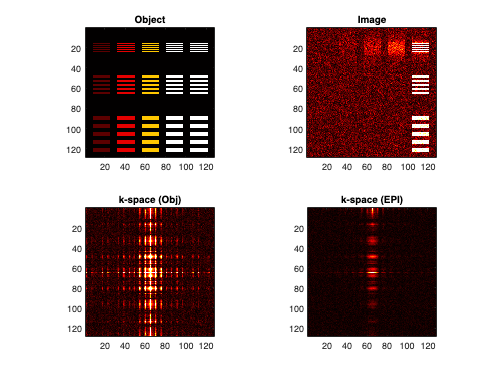

figure; hold on; colormap(hot);
subplot(2,2,1); imagesc(abs(P)); axis equal tight;
  title('Object');        caxis([0 0.075]);
subplot(2,2,2); imagesc(abs(IM_epi)); axis equal tight;
  title('Image');         caxis([0 0.5]);
subplot(2,2,3); imagesc(abs(kspc(:,:,1))); axis equal tight;
  title('k-space (Obj)'); caxis([0 150]);
subplot(2,2,4); imagesc(abs(k_epi)); axis equal tight;
  title('k-space (EPI)'); caxis([0 300]);

## Demonstrate CENTER-OUT EPI of object

disp('Demonstrate CENTER-OUT EPI of object');

Demonstrate CENTER-OUT EPI of object


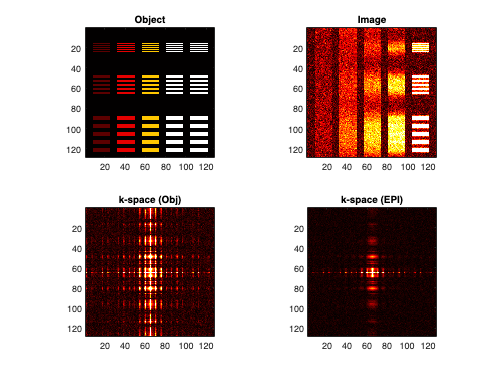

figure; hold on; colormap(hot);
subplot(2,2,1); imagesc(abs(P)); axis equal tight;
  title('Object');        caxis([0 0.075]);
subplot(2,2,2); imagesc(abs(IM_cntout)); axis equal tight;
  title('Image');         caxis([0 0.5]);
subplot(2,2,3); imagesc(abs(kspc(:,:,1))); axis equal tight;
  title('k-space (Obj)'); caxis([0 150]);
subplot(2,2,4); imagesc(abs(k_cntout)); axis equal tight;
  title('k-space (EPI)'); caxis([0 300]);